outputdir = "D:\\Whale Data\\Raw Audio Data\\";
inputdirs = [...
    "D:\\Whale Data\\POIData\\1",...
    "D:\\Whale Data\\POIData\\2",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\BallenyIslands2015\\wav",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\casey2017\\wav",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\kerguelen2015\\wav",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\MaudRise2014\\wav",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\RossSea2014\\wav",...
    ];

outputnames = [...
    "FalseBay2022Aug",...
    "FalseBay2022Oct",...
    "BallenyIslands2015",...
    "CaseyIslands2017",...
    "KerguelenIslands2015",...
    "MaudRise2014",... %weird format thing??
    "RossSea2014",...
    ];

dtformats = [...
    "yyyyMMdd_HHmmss_SSSS",...
    "yyyyMMdd_HHmmss_SSSS",...
    "yyyyMMdd_HHmmss",...
    "yyyyMMdd_HHmmss",...
    "yyyyMMdd_HHmmss",...
    "yyyyMMdd_HHmmss",...
    "yyyyMMdd_HHmmss",...
    ];

fs = [...
    2000,...
    2000,...
    1000,...
    1000,...
    1000,...
    1000,...
    1000,...
    ];

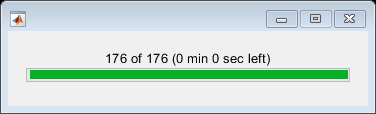

Worker 3: 
Worker 4: 
Worker 3: 
  > In audiowrite>clipInputData (line 474)
  In audiowrite (line 245)
  In 

for i = 1:numel(outputnames)
    targetdir = outputdir + outputnames(i);
    adc = AudioDataConverter(inputdirs(i), targetdir, dtformats(i), fs(i));
    adc.convert();
end

sfbFreq = {...
    [25, 1000],...
    [25, 1000],...
    [10, 500],...
    [10, 500],...
    [10, 500],...
    [10, 500],...
    [10, 500],...
    };

for i = 1:2
    sc = SpectrogramCreator(outputnames(i));
    f = sfbFreq{i};
    sc.create(16, 0.05, fs(i), AudioDataConverter.L, f(1), f(2));
end

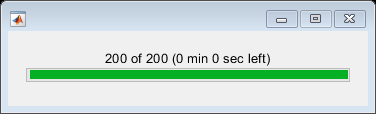

Worker 3: 
Worker 4: 
Worker 3: 
  > In audiowrite>clipInputData (line 474)
  In audiowrite (line 245)
  In 

adc = AudioDataConverter("D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\MaudRise2014\\wav", outputdir + "MaudRise2014", dtformat, 1000);
adc.convert();

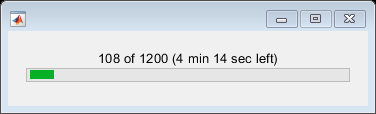

sc = SpectrogramCreator("MaudRise2014");
sc.create(16, 0.05, 1000, AudioDataConverter.L, 10, 500);

inputdirs = [...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\BallenyIslands2015\\",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\casey2017\\",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\kerguelen2015\\",
    ];

outputdir = "D:\\Whale Data\\Raw Audio Data\\";
outputnames = [...
    "BallenyIslands2015",...
    "CaseyIslands2017",...
    "KerguelenIslands2015",
    ];

dtformat = "yyyyMMdd_HHmmss";

for fidx = 1:numel(inputdirs)

    pathformatted = outputdir + outputnames(fidx);
    pathorig = inputdirs(fidx) 

    dl = DataLoader2(pathformatted, 'wav', 'single', true);
    filelist = dl.filelist;
    FIDlist = [filelist.fid];
    [filelisttimes, sidx] = sort([filelist.time]);
    filelist = filelist(sidx);
    FIDlist = FIDlist(sidx);

    files = dir(pathorig);
    annotations = convertCharsToStrings({files.name});
    idx = arrayfun(@(s) s.contains("selections.txt"), annotations);
    annotations = annotations(idx)
    ann = {};
    for fname = annotations
        T = readtable(pathorig + fname, "Delimiter","\t");
        idx = find(fname{:} == '.');
        type = extractBetween(fname, idx(1)+1, idx(end-1)-1);
        type = type.replace(".", "_");
        type = repmat(type, size(T, 1), 1);
        T(:, 'Type') = cellstr(type);
        ann{end + 1} = T;
    end
    masterTable = {};
    for T = ann
        T = T{:};
        row = table();
        row.File = convertCharsToStrings(T.BeginFile);
        if ~isempty(row)


            row.StartIdx = T.BegFileSamp_samples_;
            row.EndIdx = T.EndFileSamp_samples_;
            row.Duration = T.DeltaTime_s_;
            row.StartFrequency = T.LowFreq_Hz_;
            row.EndFrequency = T.HighFreq_Hz_;
            row.Annotation = convertCharsToStrings(T.Type);

            %match the correct file
            timestr = extractBefore(lower(row.File), ".wav");
            timestr = extractBetween(timestr, 1, strlength(dtformat));
            ftime = datetime(timestr, "InputFormat", dtformat);
            dt = seconds(row.StartIdx/1000);
            ftime = ftime + dt;
            matchedfileidx = arrayfun(@(time)find(time >= (filelisttimes'), 1, "last"), ftime);
            matchedfile = [filelist(matchedfileidx).name]';
            matchedfiletimes = [filelist(matchedfileidx).time]';
            matchedfids = [FIDlist(matchedfileidx)]';
            offset = floor(seconds(ftime - matchedfiletimes)*1000);
            dur = ceil(row.Duration * 1000);
            row.StartIdx = offset;
            row.EndIdx = row.StartIdx + dur;
            row.OrigFile = row.File;
            row.File = matchedfile;
            row.FileID = matchedfids;
            

            masterTable{end + 1} = row;
        end
    end
    masterTable = vertcat(masterTable{:});
    masterTable.AnnotationID = (1:size(masterTable, 1))';
    annotationTable = masterTable(masterTable.Annotation ~= "Unidentified_calls" & masterTable.Annotation ~= "unid", :);
    unidentifiedTable = masterTable(masterTable.Annotation == "Unidentified_calls" | masterTable.Annotation == "unid", :);
    savepath = pathformatted + "\\annotations";
    mkdir(savepath);
    save(savepath + "\\annotations.mat", "masterTable", '-mat');
end

pathorig = "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\BallenyIslands2015\\"

annotations = 1×11 string array
    "Balleny2015.BmAnt-A.selections.txt"    "Balleny2015.BmAnt-B.selections.txt"    "Balleny2015.BmAnt-Z.selections.txt"    "Balleny2015.BmD.selections.txt"    "Balleny2015.Bp20Hz.selections.txt"    "Balleny2015.Bp20Plus.selections.txt"    "Balleny2015.BpDwnswp.selections.txt"    "Balleny2015.BpHigherCall.selections.txt"    "Balleny2015.humpback.selections.txt"    "Balleny2015.minke.selections.txt"    "Balleny2015.unid.selections.txt"


pathorig = "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\casey2017\\"

annotations = 1×8 string array
    "Casey2017.Bm.Ant-A.selections.txt"    "Casey2017.Bm.Ant-B.selections.txt"    "Casey2017.Bm.Ant-Z.selections.txt"    "Casey2017.Bm.D.selections.txt"    "Casey2017.Bp.20Hz.selections.txt"    "Casey2017.Bp.20Plus.selections.txt"    "Casey2017.Bp.Downsweep.selections.txt"    "Casey2017.Unidentified.calls.selections.txt"


pathorig = "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\kerguelen2015\\"

annotations = 1×9 string array
    "Kerguelen2015.Bm.Ant-A.selections.txt"    "Kerguelen2015.Bm.Ant-B.selections.txt"    "Kerguelen2015.Bm.Ant-Z.selections.txt"    "Kerguelen2015.Bm.D.selections.txt"    "Kerguelen2015.Fin.20Hz.selections.txt"    "Kerguelen2015.Fin.20Plus.selections.txt"    "Kerguelen2015.Fin.DS.selections.txt"    "Kerguelen2015.MinkeDS.selections.txt"    "Kerguelen2015.Unidentified.calls.selections.txt"


inputdirs = [...%     "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\BallenyIslands2015\\",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\casey2017\\",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\kerguelen2015\\",...%     "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\MaudRise2014\\",...
    "D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\RossSea2014\\",...
    ];

outputdir = "D:\\Whale Data\\Raw Audio Data\\";
outputnames = [...%     "BallenyIslands2015",...
    "CaseyIslands2017",...
    "KerguelenIslands2015",...%     "MaudRise2014",... %weird format thing??
    "RossSea2014",...
    ];


for fidx = 1:numel(inputdirs)

    pathformatted = outputdir + outputnames(fidx);
    spectropath = pathformatted + "\\spectrograms\\";
    annpath = pathformatted + "\\annotations\\";
    load(annpath + "annotations.mat");
    load(spectropath + "filterbank.mat")

    threadidx = ThreadIdx(size(annotationTable, 1), 6);

    fbfs = fb.getSSamplingFreq();
    spmd %for i = 1
        while ~threadidx.complete(spmdIndex)
            try
            idx = threadidx.next(spmdIndex);
            row = annotationTable(idx, :);
            name = extractBefore(row.File, ".wav");
            spectroname = name + ".mat";        
            s = load(spectropath + spectroname).s;
            fig = figure("Visible", "off");
            fb.plotS(abs(s), true);
            t = [row.StartIdx, row.EndIdx]/1000;
            tlims = [max(row.StartIdx-500, 0), min(row.EndIdx+500, AudioDataConverter.L)]/1000;
            fbox = [row.StartFrequency, row.StartFrequency, row.EndFrequency, row.EndFrequency];
            tbox = [t(1), t(2), t(2), t(1)];
            xlim(tlims);
            hold on
            fill( tbox, fbox, 'r', "FaceAlpha",0.1, "EdgeAlpha",0.8);
            hold off
            fname = sprintf("%s (%s)", row.Annotation, extractBefore(row.File, ".wav"));
            title(fname, "Interpreter","none");
            saveas(fig, annpath + fname + ".png")
            close(fig);
            catch e
                disp(getReport(e, "extended"))
            end
        end        
    end
    
end

%these are the only datasets that are usable
outputnames = [...
    "BallenyIslands2015",...
    "CaseyIslands2017",...
    "KerguelenIslands2015",...
    ];

for idx = 1:numel(outputnames)
    gc = SEGMMCreator(outputnames(idx));
    gc.create();
end

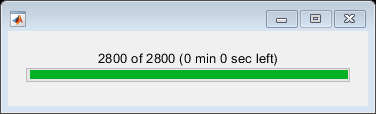

%these are the only datasets that are usable
outputnames = [...
    "BallenyIslands2015",...
    "CaseyIslands2017",...
    "KerguelenIslands2015",...
    ];

for idx = 1:numel(outputnames)
    cc = ContourCreator(outputnames(idx));
    cc.create();
end